# **Quick introduction to MATLAB**

Just some basic notes to get you comfortable with using MATLAB. Ask questions. It is the only way to learn.

# Housekeeping

%% Short-cuts: ctr+T toggles line on & ctr+R toggles line off

clear % removes items from workspace, freeing up space
close all % removes all figures / replace "all" if you want to remove specific figure
clc % clear command window

# Creating matrices

A = [1 2 3; 4 5 6; 7 8 9];

B = [
1 2 3
4 5 6
7 8 9];


# Matrix operations

C1 = A + B;
% C2 = A .+ B % Why does this not work?

D = [1,2,3,4].*[1,2,3,4];
% [1,2,3,4]*[1,2,3,4] % Why does this not work?

E = [1,2,3,4].^2;

# Matrix building functions

zeros(2, 3);
ones(3, 3);
eye(4);
F = 1:4;
G = 0.32:0.1:0.6;

# Accessing elements of a matrix

G(1, 2);
G(:, 1);
G(1, :);
G(end, end);
diag(G);

#### Quick exercise (what will these do?)

H=[-1 2 -3; 4 5 -6];
H(H<0)=0;
H(H>0)=1;
H(1,find(H(1,:)<0))=0;
H(find(H<0|H>=5))=0;

# More matrix operations

I = [1 2; 5 6; 8 9];
J = I(:); % vectorisation of I
reshape(J, 3, 2);
K = J'; % transpose

# Built in functions

sort(K);
size(K);
[m,n] = size(K);
sum(K);
min(K);
L = inv(A); % can only take inverse of a square matrix

[M, N] = eig(L); % eignvectors and eigenvalues of L
kron(A, K); % kronecker product of A, K

# Save results

save results1

save results2 A

load results1 % imports into your workspace

# Random numbers

rand(2, 3);
randn(2, 3); % What is the difference between these two commands?

Quick exercise, build two $N\times1$ vectors. Let us call them $k$ and $y$. Entries of $y$ and $k$ are defined by the equations:


$$y_t = 3 + 0.5  x_{1t} + 0.9 x_{2t} + e_t$$



$$k_t = 3 + 0.5  x_{1t} + 0.9 x_{2t}
$$


$x_{it}$ is Normal(i, 2) and $e_t$ is Normal(0, 1)

Using OLS, estimate the coefficients for the $y$ and $k$ equations

N = 50;
X1 = 1 + 2 * randn(N, 1);
X2 = 2 + 2 * randn(N, 1);
Y = 3 + 0.5 * X1 + 0.9 * X2 + randn(N, 1);
K = 3 + 0.5 * X1 + 0.9 * X2;
X = [ones(N, 1) X1 X2];
BetaY = inv(X' * X) * X' * Y;
BetaK = inv(X' * X) * X' * K;

What happens as we increase the size of $N$?

# Graphics

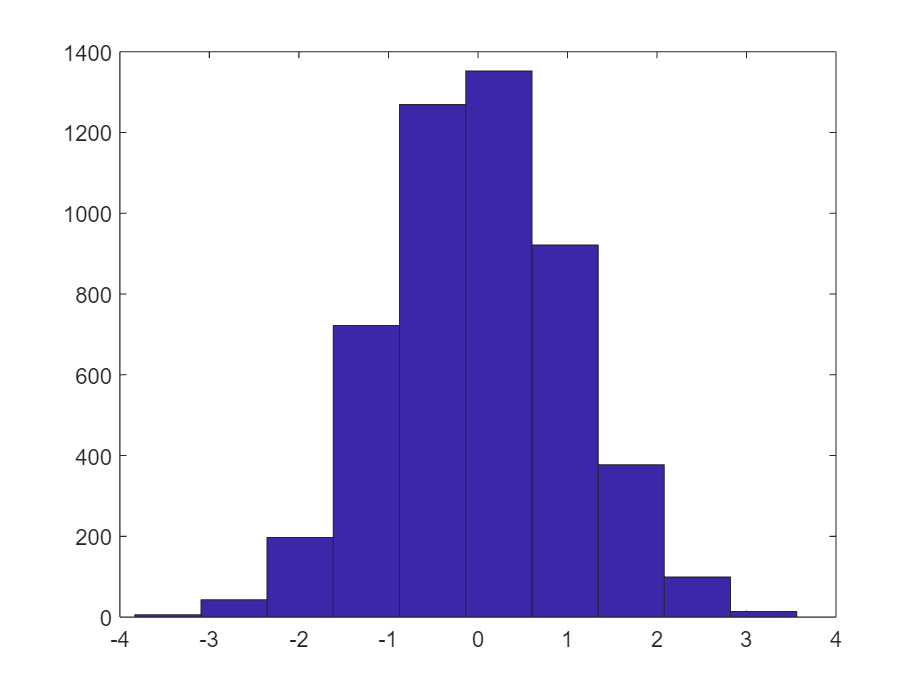

x=randn(5000,1);
hist(x);

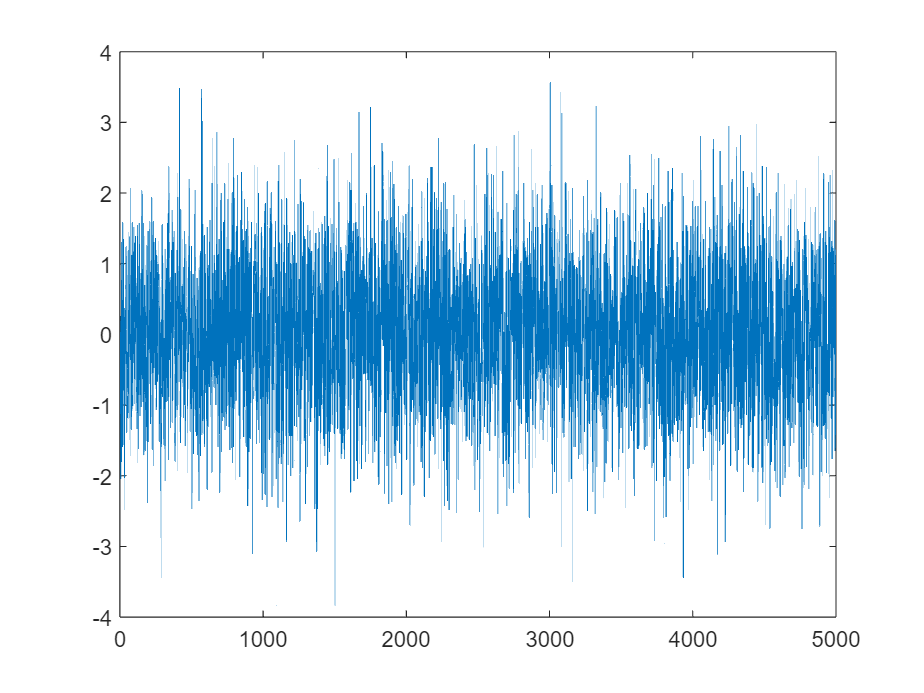

 plot(x);

# Control flow

FOR loops are used when a set of statements is to be repeated a fixed predetermined number of times. We can use something like a for loop

for i = 1:1:10
    z(i) = i;
end

What do you think this loop does?

We can also have nested for loops, 

for i=1:1:10
    for j=1:1:10
        Z(i,j)=1/(i+j-1);
    end
end

While loops are also important.  

a=1;
while a<=10
    a=a+1;
end

They are often easier to interpret and give you a direct stopping criteria. 

The IF statement execute a set of statements if a condition is satisfied.

x = -1 + 2*rand(100,1);
for i=1:1:100
    if x(i)>0
        d(i)=1;
    elseif x(i)<0
        d(i)=-1;
    else
        d(i)=0;
    end
end

What does the code above do? Can we unpack it?